# Neurotechnology, Brains and Machines: Week 4

Sam Michalka

Skim through this notebook and then read Chapter 5 from Martinez & Cho (Statistics in Matlab: a Primer) or some other source on hypothesis testing, t-tests, and bootstrapping (which we did last week).  Besides the guidance given on how to approach data analysis, this notebook assumes you have already prepared yourself with external sources (unlike the last notebook, which walked you through things step by step).  

There are numerous stats resources out there, and one goal here is to have you practice finding your own resources and applying them (with some guidance).  However, if you're feeling stuck, there are some suggestions below, or touch base with Sam/NINJAs (don't struggle with seeking out resources for more than 30 minutes).  Here are some suggestions:

Matlab documentation can be found using "doc" then "ttest" or "ttest2". 

Slides on hypothesis testing and bootstrapping: [http://www.uoguelph.ca/~psystats/presentations_6380_fall06/Bootstrapping%20Presentation.pdf](http://www.uoguelph.ca/~psystats/presentations_6380_fall06/Bootstrapping%20Presentation.pdf)

Khan academy videos:

[https://www.khanacademy.org/math/statistics-probability/significance-tests-confidence-intervals-two-samples/comparing-two-means/v/statistical-significance-experiment](https://www.khanacademy.org/math/statistics-probability/significance-tests-confidence-intervals-two-samples/comparing-two-means/v/statistical-significance-experiment)

[https://www.khanacademy.org/math/statistics-probability/significance-tests-one-sample](https://www.khanacademy.org/math/statistics-probability/significance-tests-one-sample)

Explanation of types of t-test. (Dependent and paired t-tests are the same thing. This example shows how to do this in excel, but you can easily look up how to do this in Matlab 

[http://benbaab.com/steinberg/class5.html](http://benbaab.com/steinberg/class5.html)

We'll start with a couple of useful resources.  One can use the function tpdf(x,nu), as shown in the code below, or get the same result by first making the distribution object (like we have done in previous examples):

mydistobj = makedist('tLocationScale','mu',0,'sigma',1,'nu',10); 

where 'nu' refers to the degrees of freedom. Then you can call 

mydistobj.pdf()

This plot just shows the t-distributions for various degrees of freedom.

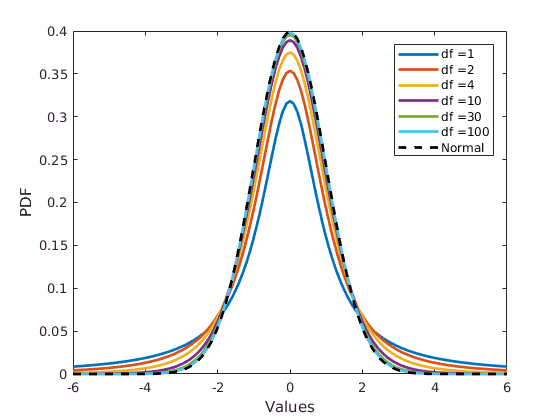

x = -6:.1:6; % Values on x-axis to evaluate and plot

dfs = [1 2 4 10 30 100]; % Various degrees of freedom to plot
for d = 1:length(dfs) %Loop through all dfs
    plot(x,tpdf(x,dfs(d)),'LineWidth',2);
    legval{d} = strcat('df = ',num2str(dfs(d))); % Record dfs for legend
    hold on
end
plot(x,normpdf(x),'k--','LineWidth',2)
legval{d+1} = 'Normal';
legend(legval); xlabel('Values');ylabel('PDF')
hold off

Last week, we used the KS plots (with some confidence bounds) to investigate how well our data and models (e.g., exponential and inverse gaussian) aligned. The function kstest() is useful for investigating the same thing and formally testing it.

Here we are using the KS test to determine if the data fit a standard normal distribution (but we could specify a different distribution instead).

n = 100; % You can manipulate this value
mydata = normrnd(0,1,n,1);  % Select random values from a normal distribution
mydist = makedist('Normal'); % standard normal distribution by default
[h,p,ksstat,cv] = kstest(mydata) %read the documentation on this to understand the outputs

h = logical
   0


p = 0.5335

ksstat = 0.0790

cv = 0.1340

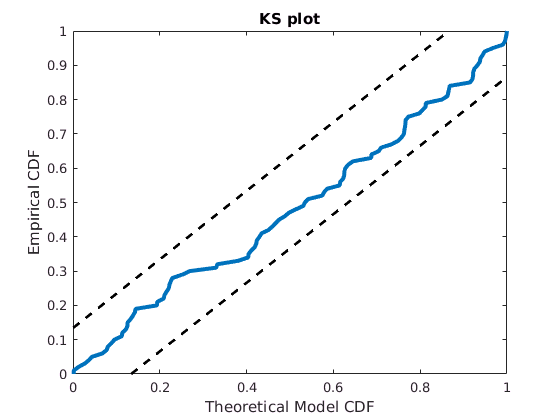

[mycdf,ebins] = ecdf(mydata); % find the empirical cdf for the data
% Make the ks plot with confidence bounds
plot(mydist.cdf(ebins),mycdf,'LineWidth',3);
hold on
plot([0 1], [0 1]+cv,'k--','LineWidth',2);
plot([0 1], [0 1]-cv,'k--','LineWidth',2);
axis([0 1 0 1]) %... with fixed axes.
title('KS plot'); xlabel('Theoretical Model CDF'); ylabel('Empirical CDF'); hold off

# Guidelines for analysis - READ THIS!

Here is a general process to follow for analyzing data:

1) Plot the data (boxplot, histogram, whatever makes sense)

2) Make sure that the data are complete, or determine/justify what to do with incomplete data (e.g, remove points, estimate replacements).

3) State what you are trying to answer (e.g., what is the difference between values for category A and B, and is this meaningful) and how these data are organized (e.g, the values are in vector "values" and the categories are represented by the strings 'A' and 'B' in the vector "group"). 

4) Determine what types of tests/measurements are appropriate to answer your question. Consider the assumptions/constraints.

5) Calculate appropriate measurements / tests.

6) Summarize your findings in a sentence or two.  (If you want to get fancy, you can look up APA style for reporting statistical tests.)

**Use this process to analyze the two sets of data provied below (show your plots, code, comments, and descriptions/summaries).**

Specifically for this assignment, please be sure to include each of the following measurements / tests (and any other measurments/tests you deem appropriate):

- effect size

- results of hypothesis testing using bootstrapping [also include a histogram with lines for your observed value and the critical values]

- results of hypothesis test using t-test , [also visually represent this with the t-distribution, critical values and t-value for the sample]

- confidence interval using t-distribution with a description of what this represents

In a typical analysis, one would choose to use either a standardized analysis (e.g., t-test) or a bootstrapping method. Here, we will do both for the sake of learning/practice.  You can use a default of 95% confidence intervals and hypothesis tests (alpha = 0.05).

**Other important advice:**

If you're struggling with one part of the process above or one of the measurements/tests, make yourself a note to get help on that part and move on.  Don't spend hours going in circles on something alone when you are surrounded by people who want to help. Ideally you get help before you turn this in, and otherwise, make good use of the notebook debrief time at the beginning of class.

# Data Set: Mouse in a Maze

Background: Mice tend to avoid open spaces (turns out these are dangerous for prey). Scientists study mice using an elevated plus-maze:

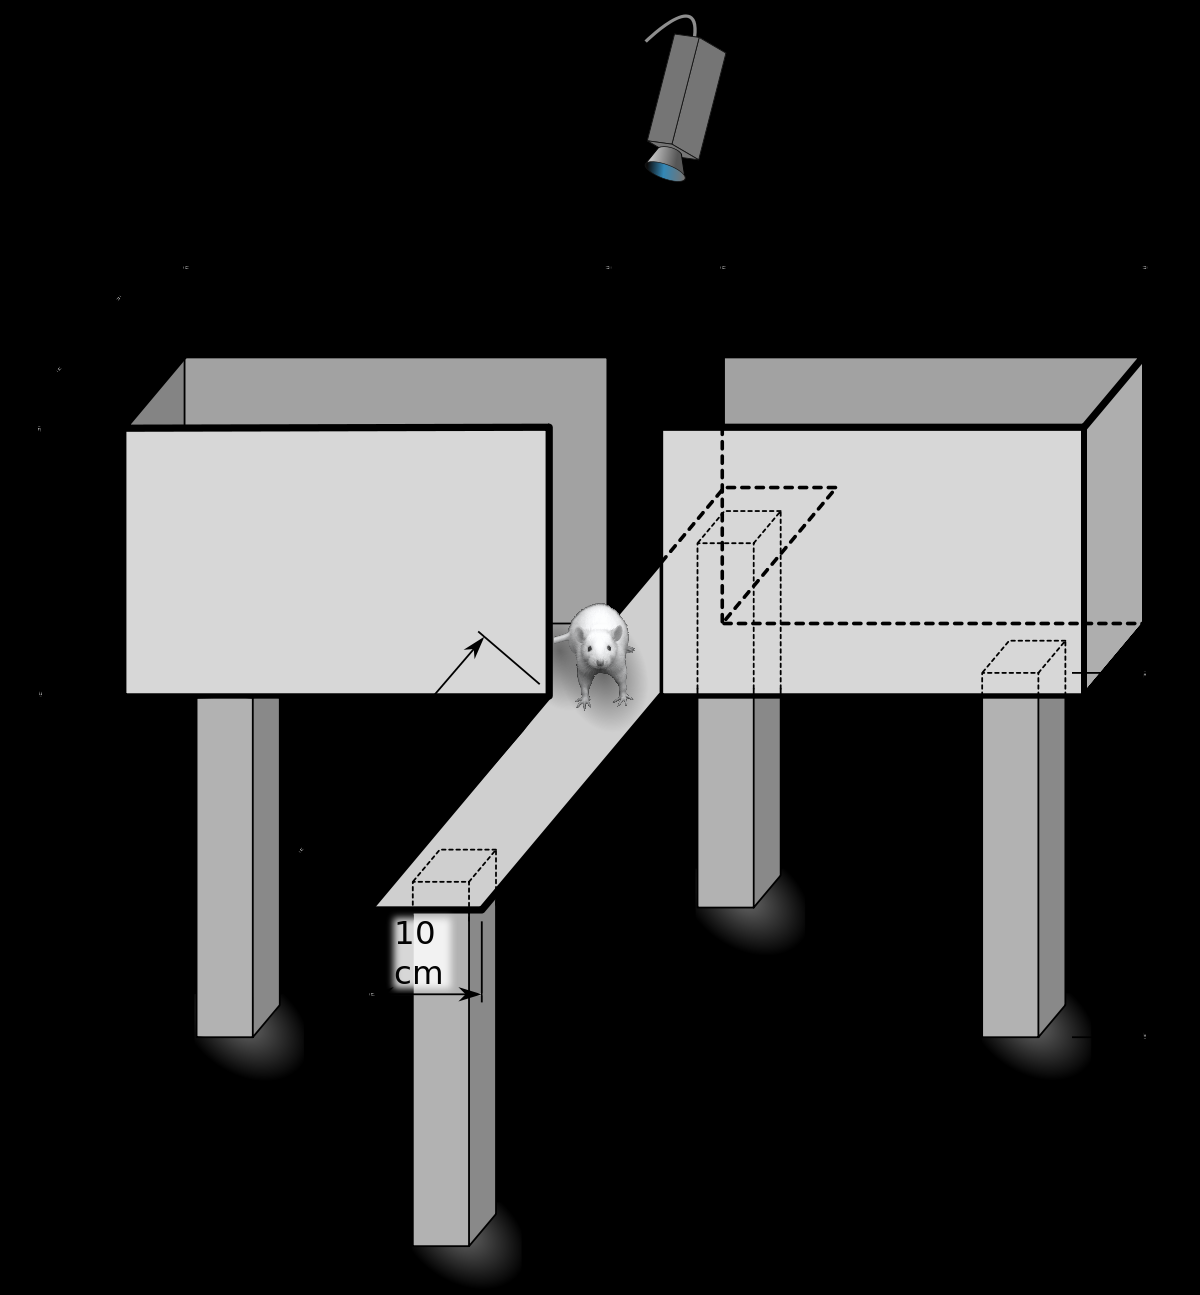

One common this to look at is the percentage of time that mice spend in the open (exposed) arm of the maze, which is considered a proxy measure of anxiety.  If mice were indifferent to the open vs closed arm of the maze, then we would expect to observe the mouse in the open arm of the maze approximately 50% of the time. 

These data give the percentage of time that each of 15 mice spent in the open arm. Use the process above to investigate how this relates to the hypothesized 50% (if indifferent). 

load('mouse.mat');

% Answer text and code goes here

1) Plot the data (boxplot, histogram, whatever makes sense)

2) Make sure that the data are complete, or determine/justify what to do with incomplete data (e.g, remove points, estimate replacements).

3) State what you are trying to answer (e.g., what is the difference between values for category A and B, and is this meaningful) and how these data are organized (e.g, the values are in vector "values" and the categories are represented by the strings 'A' and 'B' in the vector "group"). 

4) Determine what types of tests/measurements are appropriate to answer your question. Consider the assumptions/constraints.

5) Calculate appropriate measureHypments / tests.

6) Summarize your findings in a sentence or two.  (If you want to get fancy, you can look up APA style for reporting statistical tests.)

## Inspect the data

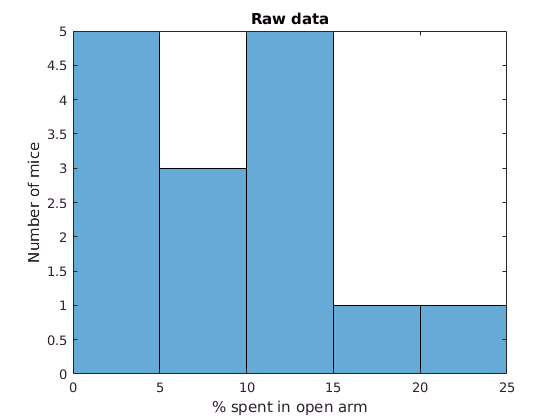

histogram(openarm,'NumBins',5); title('Raw data'); xlabel('% spent in open arm'); ylabel('Number of mice')

min(openarm)

ans = 0

max(openarm)

ans = 20.7000

median(openarm)

ans = 9.2000

std(openarm)

ans = 6.4017

mean(openarm)

ans = 8.6200

The data seems reasonable. The minimum value of 0 is indicative of possible missing data, but in this case it seems likely that a mouse just spent *no time at all* in the exposed section of the maze.

## Plan Tests

**Effect size** is not really an appropriate measure here because there isn't a "procedure" we are measuring the effect of, or a control group to compare against. In principle, we could measure the effect of "being given the choice which arms to visit" instead of the control "being forced  into arms by a random number generator", but that's not really the point of effect size.

Blindly applying the calculations anyway, using the standard deviation of the available data on "affected" rats...

effectSize = (mean(openarm)-50)/std(openarm)

effectSize = -6.4639

**Hypothesis Testing using bootstrapping **also doesn't really apply in this case because we *don't have the data necessary* to ask the question of "in a universe where the true mean exposed time is 50%, how likely are we to observe a result at least this extreme?".

In particular, because we have 0 samples greater than 50%, using all of our data combined as a pool still isn't representing a world where the true mean is 50%.

We can go through the motions anyway...

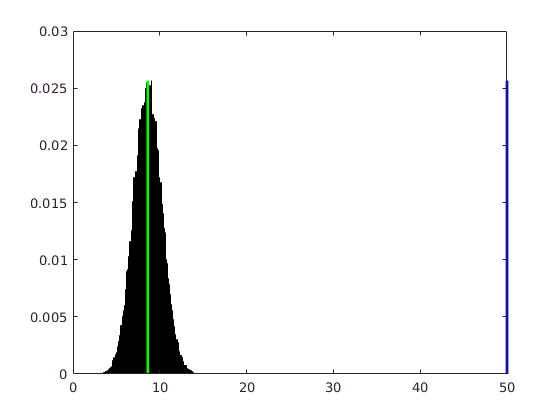

Nall = length(openarm); %Length of all samples available
Ntest = length(openarm); % Length of sample group
Nboots = 10000; % Number of bootstrap iterations

for i = 1:Nboots  % For each bootstrap iteration
    samp = openarm(randsample(Nall,Ntest,1)); % random sample with replacement of ISIs that is length of the sample
    sampMean(i) = mean(samp); %store the mean in a vector
end

h=histogram(sampMean, 'normalization', 'probability'); %storing the output of histogram gives us useful info
hold on
plot([mean(openarm) mean(openarm)],[0 max(h.Values)],'g','LineWidth',2)
plot([50 50],[0 max(h.Values)],'b','LineWidth',2)
hold off

As expected, because we don't have a control dataset to compare against, this is just a straightforward demonstration of the Central Limit Theorem. This is not a meaningful result.

Alternately, we could have computed the probability of observing a mean of 50% or higher given the population we measured, but that's trivially 0, and not really meaningful either.

**Hypothesis testing using t-statistics** Finally, t-statistics promises to provide a useful result in the form of a One Sample t-Test. We wish to test the hypothesis that there is a difference between the behavior of the mice we tested and the claimed value of 50%. Because we have prior reason to believe mice would avoid the open areas, a one-tailed test is appropriate here.

First, we will check that our data fits a normal distribution, which is a prerequisite for using a One Sample t-Test

mydist = fitdist(openarm, 'Normal') % standard normal distribution by default

mydist =   NormalDistribution

  Normal distribution
       mu =   8.62   [5.07486, 12.1651]
    sigma = 6.4017   [4.68685, 10.0961]


[h,p,ksstat,cv] = kstest(openarm, 'CDF', mydist) %read the documentation on this to understand the outputs

h = logical
   0


p = 0.9604

ksstat = 0.1214

cv = 0.3376

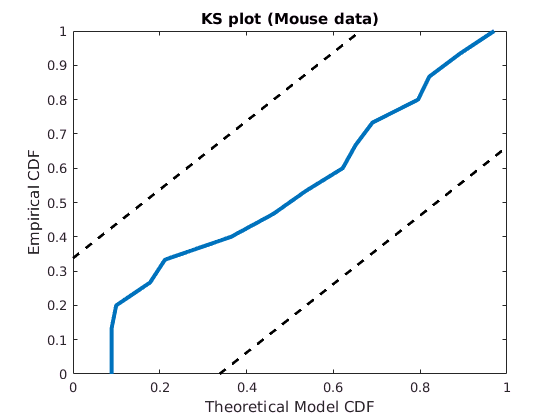

[mycdf,ebins] = ecdf(openarm); % find the empirical cdf for the data
% Make the ks plot with confidence bounds
plot(mydist.cdf(ebins),mycdf,'LineWidth',3);
hold on
plot([0 1], [0 1]+cv,'k--','LineWidth',2);
plot([0 1], [0 1]-cv,'k--','LineWidth',2);
axis([0 1 0 1]) %... with fixed axes.
title('KS plot (Mouse data)'); xlabel('Theoretical Model CDF'); ylabel('Empirical CDF'); hold off

Fortunately(?) the dataset we have is small enough that a normal distribution does fit it reasonably well, so we can proceed.

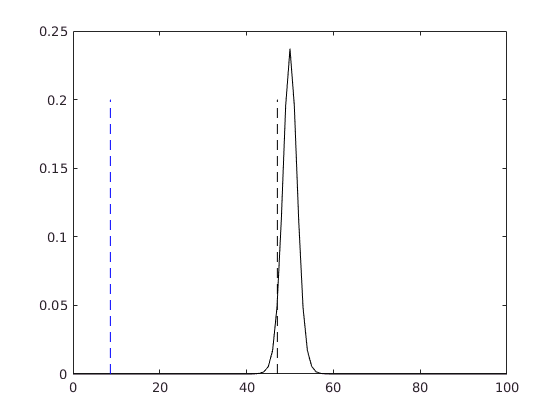

tdist = makedist('tLocationScale','mu',50,'sigma',std(openarm)/sqrt(length(openarm)),'nu',length(openarm)-1);
x = [0:1:100];
plot(x, tdist.pdf(x),'k')
hold on
plot([1 1]*mean(openarm),[0 0.2],'b--')
plot([1 1]*tdist.icdf(0.05),[0 0.2],'k--')
hold off

p=tdist.cdf(mean(openarm))

p = 2.5145e-13

## Conclusions

The 15 mice tested spent an average of 8.6% of the time in one of the exposed arms of the maze. This is less than 50% with a significance of p=2.5*10^-19, so the result is significant.

# Check-in

If you have really struggled with this assignment so far and have already spent more than 3.5 hours on the stats part, then note what you found difficult here and just pick one of the following two examples to complete.

If you're not struggling with this, yay! Proceed and enjoy the tryptophan and vigilance.

Due to an unusually busy weekend schedule, I had insufficient time to finish this assignment before class. I will attempt to resubmit this evening.

# Data Set: Tryptophan 

Background: The purpose of this study is to examine the extent to which dietary tryptophan (an essential amino acid) can increase serotonin (5-HT) in the raphe nucleus of rat brain. One groups of rats was allowed ad lib access to standard chow and a second group to chow that was supplemented with tryptophan. After a week, rats were sacrificed and the amount of 5-HT was assessed in sections of the raphe nucleus of their brains (sorry, fictional mice).

Data supplied by Greg Carey.

load('Tryptophan.mat'); % 

Analyze these data using the guidelines above.

% Answer text and code goes here.

# Dataset: Vigilance 

Background: A cognitive neuroscientist interested in the effects of diurnal variation on attention administered a vigilance task to a group of students at 9:00 in the morning and then again at 4:00 in the afternoon of the same day. The number of errors in vigilance was recorded.

Data provided by Greg Carey.

load('Vigilance.mat');

Analyze these data using the guidelines above.

% Answer text and code goes here.